# 数据提取

% 读取数据
filename = 'ExpDat_20250310PQM.txt'; % 文件名
data = readtable(filename); % 读取整个表格数据

% 提取数据列
Temp = data{:, 1}; % 温度，单位：℃
Time = data{:, 2}; % 时间，单位：min
DTA = data{:, 3}; % DTA，单位：uV/mg
Mass = data{:, 4}; % 质量，单位：mg

# 画TG

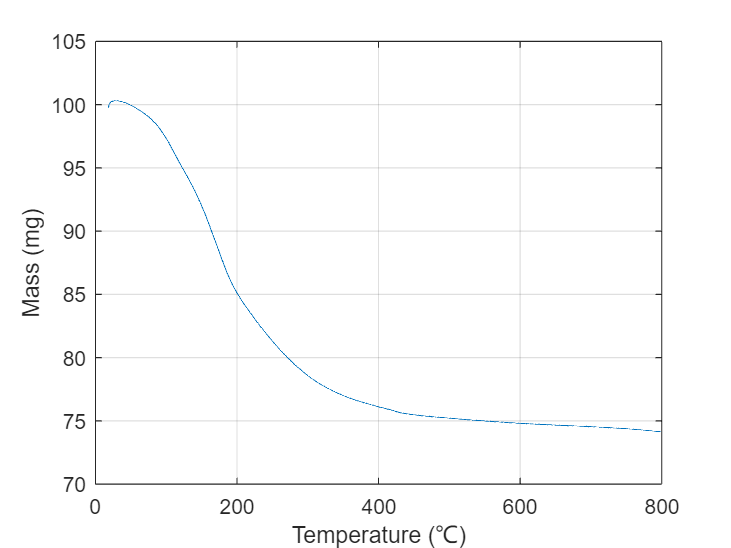

% 绘制温度-质量曲线
figure;
plot(Temp, Mass);
xlabel('Temperature (℃)');
ylabel('Mass (mg)');
grid on;

# 画DTG

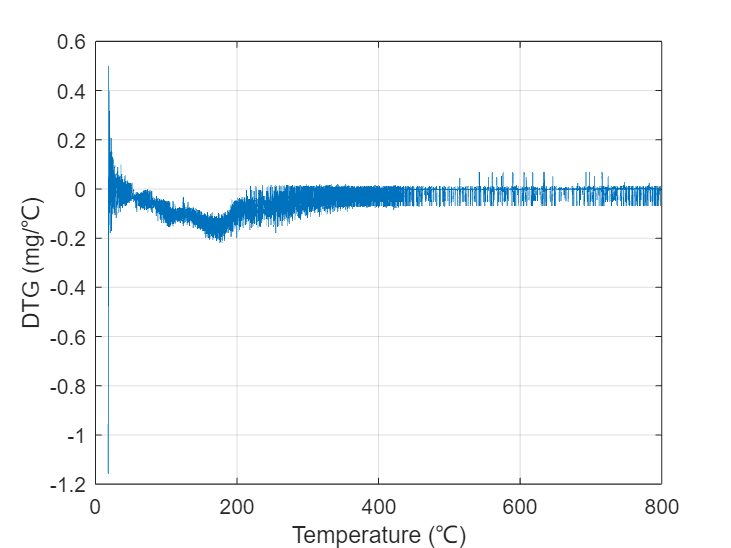

% 计算 DTG（质量对温度的导数）
dTemp = gradient(Temp); % 温度的变化量
dMass = gradient(Mass); % 质量的变化量
DTG = dMass ./ dTemp; % DTG = dMass/dTemp

% 绘制温度-DTG曲线
figure;
plot(Temp, DTG);
xlabel('Temperature (℃)');
ylabel('DTG (mg/℃)');
grid on;

# 画滤波DTG

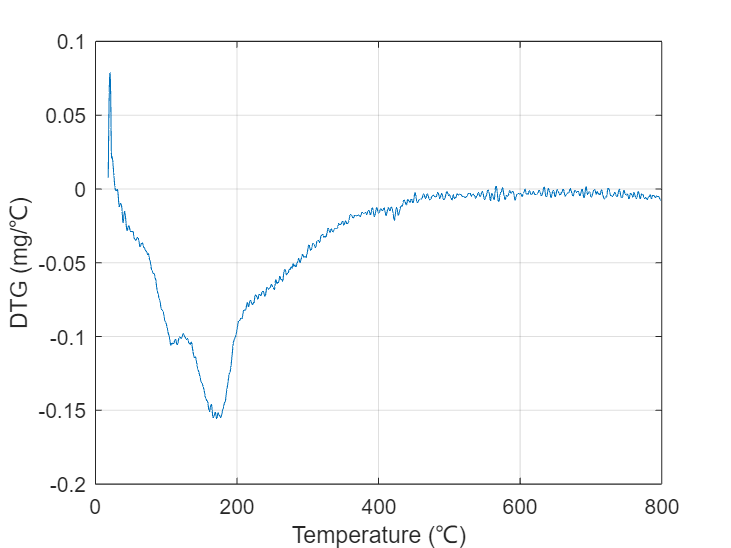

%进行loess滤波
DTG_smoothed = smoothdata(DTG, 'loess', 450);

% 绘制温度-DTG曲线
figure;
plot(Temp, DTG_smoothed);
xlabel('Temperature (℃)');
ylabel('DTG (mg/℃)');
grid on;

# 输出数据 Temp Mass DTG_smoothed

A=[Temp Mass DTG_smoothed];
writematrix(A,'output.txt', 'Delimiter', 'tab');